clc, close, clear all


load finger_ischaemia.mat

% Convert the first image from RGB to Y component and store it
Y = rgb2y(finger1_normal);
Y = imresize(Y, [145, 220]);

Y2 = rgb2y(finger2_normal);
Y2 = imresize(Y2, [145, 220]);

Y3 = rgb2y(green);
Y3 = imresize(Y3, [145, 220]);

figure
imshow(Y)


Y = rgb2y(whitelight);
Y = imresize(Y, [145, 220]);

% Construct synthetic hypercube with the same spectrogram
% Expand the array to a third dimension
expandedArray = repmat(Y, [1, 1, 190]);

% Permute the dimensions to get a 145 x 190 x 220 array
syn_hcube = permute(expandedArray, [1, 3, 2]);


% Construct synthetic hypercube with different spectrogram

% Initialize an empty array for the synthetic hypercube
syn_hcube = zeros(145, 190, 220);

% Randomly select between Y, Y2, and Y3 for each slice in the third dimension
for i = 1:190
    choice = randi([1, 3]); % Randomly select a number between 1 and 3
    switch choice
        case 1
            slice = Y;
        case 2
            slice = Y2;
        case 3
            slice = Y3;
    end
    % Fill the i-th slice in the second dimension with the selected image
    syn_hcube(:, i, :) = permute(slice, [1, 3, 2]);
end


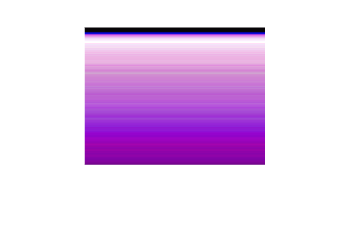


%% displaying hyperspectral image through hypercube
wavelength = linspace(0.3, 1.0, 220); % calibrate this

hcube = hypercube(syn_hcube, wavelength);
img = colorize(hcube,'Method', 'rgb', 'ContrastStretching', true);
% img = colorize(hcube, 'Method', 'rgb')
imshow(img)

figure; % Create a new figure window
imagesc(Y);
colorbar; % Add a colorbar to indicate the scale of values
xlabel('Dimension 2 (e.g., Wavelength or Time)');
ylabel('Dimension 1 (e.g., Spatial Locations)');
title('Visualization of the 145x220 Spectrum');


slice = syn_hcube(:,20,:)
slice = squeeze(slice)


Convert RGB into just Y component of YUV

function Y = rgb2y(RGB)
    % Transformation matrix to get Y component
    transformMat = [0.299, 0.587, 0.114];
    % Apply the matrix to each pixel
    Y = double(RGB(:,:,1)) * transformMat(1) + double(RGB(:,:,2)) * transformMat(2) + double(RGB(:,:,3)) * transformMat(3);
end